# **DSP Lab 9**

## **Syed Asghar Abbas Zaidi **

### **07201, Spring 2023**

**Defining the sampling frequency, creating the composite signal.**

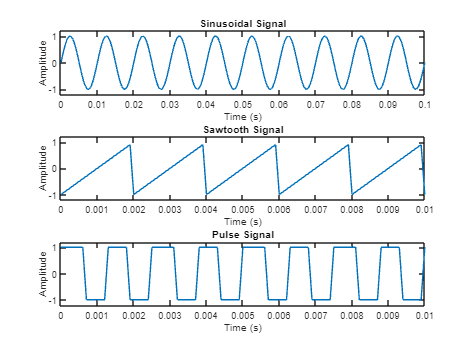

% Define the sampling frequency
fs = 10000; % Hz

% Create a time vector spanning from 0 to 1 second
t = 0:1/fs:1;

% Generate the individual signals
f1 = 100; % Frequency of sinusoidal signal (Hz)
f2 = 500; % Frequency of sawtooth signal (Hz)
f3 = 800; % Frequency of pulse signal (Hz)

% Individual signals
sinusoidal_signal = sin(2*pi*f1*t);
sawtooth_signal = sawtooth(2*pi*f2*t);
pulse_signal = square(2*pi*f3*t);

% Plot individual signals
figure;
subplot(3,1,1);
plot(t, sinusoidal_signal);
title('Sinusoidal Signal');
xlabel('Time (s)');
ylabel('Amplitude');xlim([0 0.1]);ylim([-1.2 1.2])

subplot(3,1,2);
plot(t, sawtooth_signal);
title('Sawtooth Signal');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 0.1]);xlim([0 0.01]);ylim([-1.2 1.2])%keep in mind the different time-scale

subplot(3,1,3);
plot(t, pulse_signal);
title('Pulse Signal');
xlabel('Time (s)');
ylabel('Amplitude');xlim([0 0.01]);ylim([-1.2 1.2])

#### Analysis:

This MATLAB script sets the sampling frequency to 10 kHz and tries a composite signal comprising three individual signals: sinusoidal, sawtooth, and pulse. Composite signal will be created in the upcoming section. Each signal has a different frequency (100 Hz, 500 Hz, and 800 Hz respectively). The time vector spans from 0 to 1 second, with a step size determined by the sampling frequency. The individual signals are created using built-in MATLAB functions for sine, sawtooth, and square waves. Then, each signal is plotted separately on a figure with three subplots, each representing one of the individual signals. The plots display the amplitude of the signals over time, with specific adjustments to the time range and y-axis limits for better visualization.

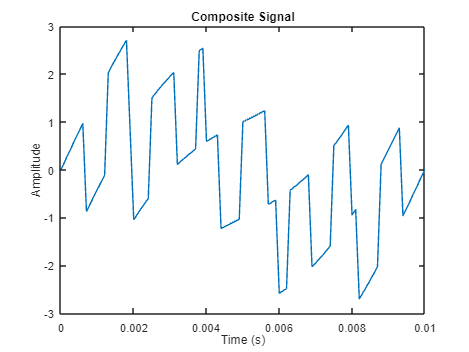

% Generate composite signal
composite_signal = sinusoidal_signal + sawtooth_signal + pulse_signal;

% Plot composite signal
figure;
plot(t, composite_signal);
title('Composite Signal');
xlabel('Time (s)');
ylabel('Amplitude');xlim([0 0.01]); %Keep in mind the time-scale

#### Analysis: 

The code combines three signals (sinusoidal, sawtooth, and pulse) into one composite signal by adding them together. It then plots this composite signal, focusing on the first 0.01 seconds for clarity.

#### Getting the FFT of the composite Signal

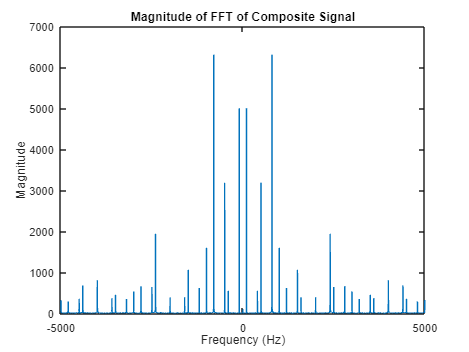

% Calculate FFT of the composite signal
fft_composite_signal = fftshift(fft(composite_signal));

% Determine frequency axis
N = length(composite_signal); % Length of the signal
df = fs / N; % Frequency resolution
frequencies = (-fs/2) + df*(0:N-1); % Frequency axis centered at 0

% Plot magnitude of FFT against frequency
figure;
plot(frequencies, abs(fft_composite_signal));
title('Magnitude of FFT of Composite Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

#### Analysis: 

The MATLAB code computes the Fast Fourier Transform (FFT) of the  composite signal and shifts its frequency components to center them  around zero using the 'fftshift' function. It then determines the  frequency axis by calculating the frequency resolution ('df') based on  the sampling frequency and signal length, and creates a frequency axis  centered at zero. Finally, the magnitude of the FFT is plotted against  frequency on a new figure, with frequency values on the x-axis and the  corresponding magnitude on the y-axis, providing insights into the frequency content of the composite signal.

### **100Hz Filter specification**

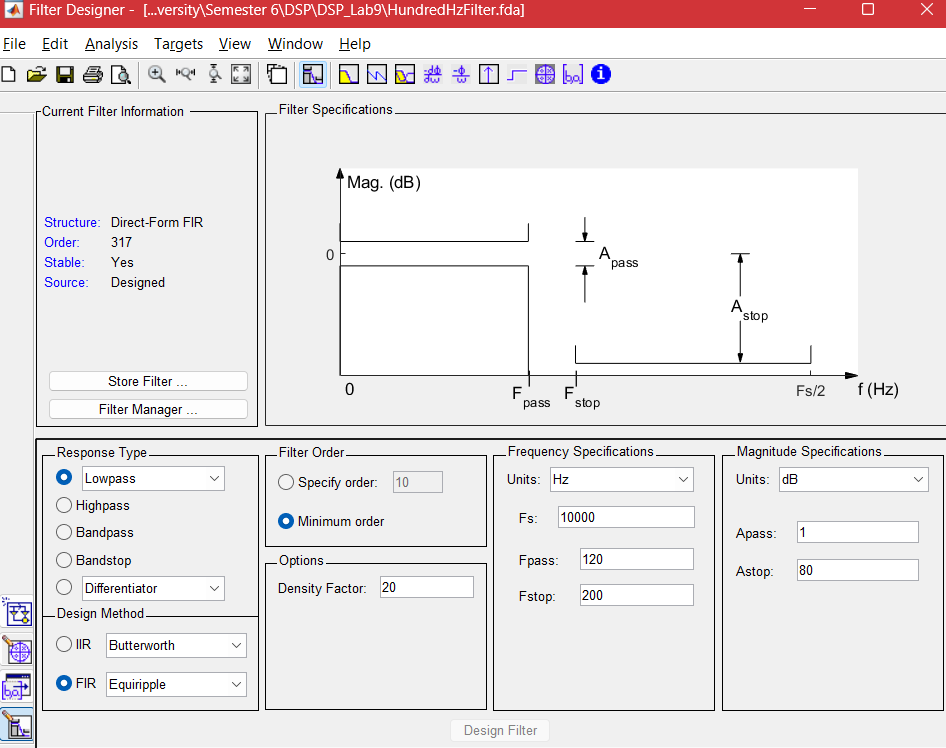

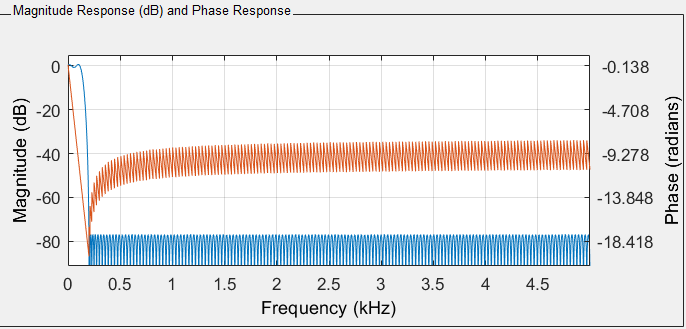

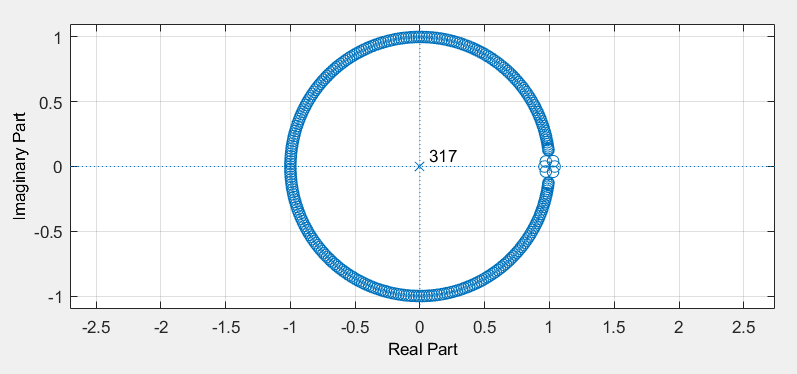

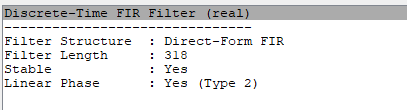

#### Analysis and what can we do with this Filter: 

Based on the specifications provided, the filter designed using FDAtool in MATLAB is a low-pass filter, designed using the Equiripple method with a minimum order. The density factor is set to 20. The sampling frequency (Fs) is 10,000 Hz. The passband frequency (Fpass) is 120 Hz, and the stopband frequency (Fstop) is 200 Hz. In terms of attenuation levels, the passband ripple (Apass) is set to 1 dB, indicating minimal allowable variation in the passband, while the stopband attenuation (Astop) is set to 80 dB, indicating a very high level of attenuation required in the stopband.

This filter will effectively attenuate frequencies beyond 200 Hz while allowing frequencies up to 120 Hz to pass through with minimal distortion. The equiripple design method ensures that the filter meets the given specifications with minimum order, providing efficient frequency response characteristics. With a stopband attenuation of 80 dB, it will significantly suppress frequencies above 200 Hz, making it suitable for applications requiring stringent stopband attenuation, such as anti-aliasing in signal processing or noise filtering in audio applications

### **500Hz filter specification **

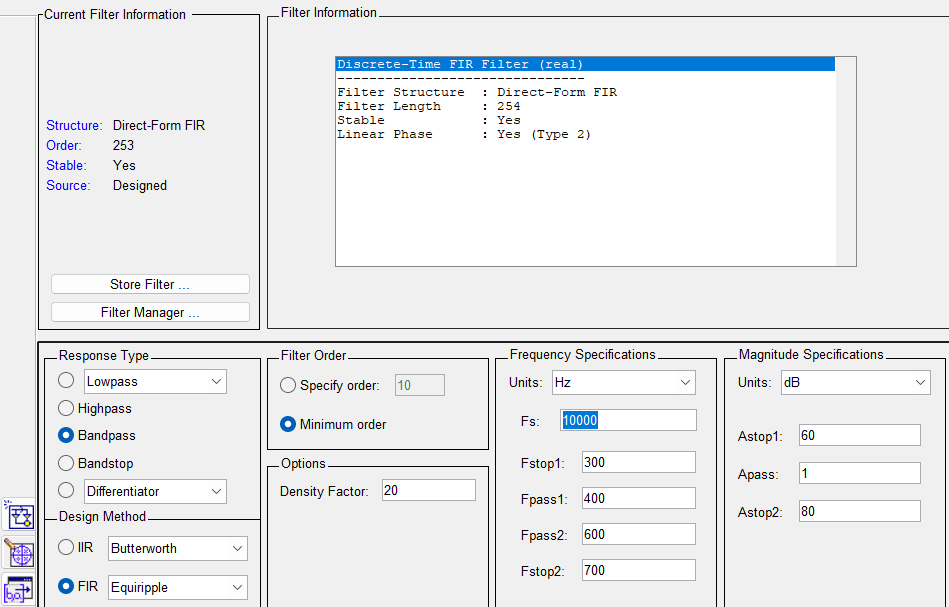

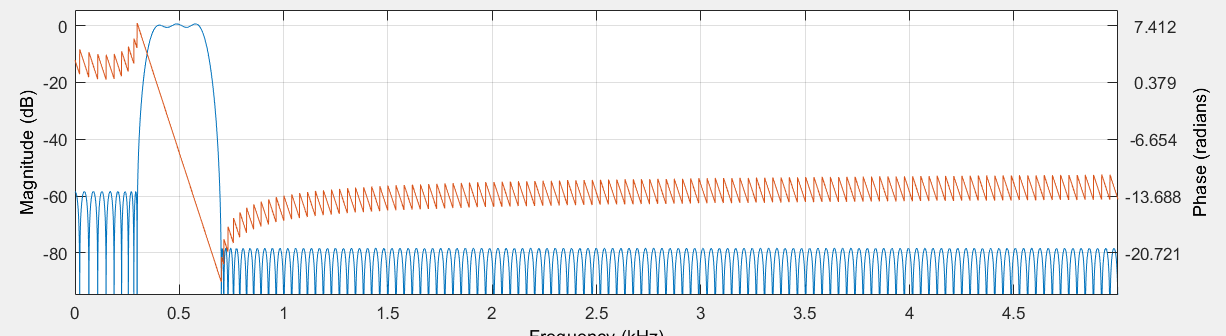

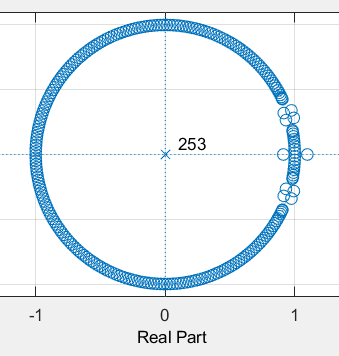

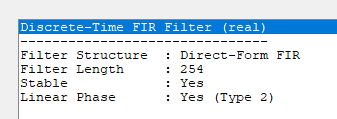

#### Analysis: 

The second filter designed with FDAtool in MATLAB differs from the first in that it is a bandpass filter instead of a low-pass filter. Its design specifications include an equiripple FIR design method with a minimum order and a density factor of 20. The sampling frequency (Fs) remains at 10,000 Hz. The bandpass filter has two passbands: one ranging from 400 Hz to 600 Hz and the other ranging from 300 Hz to 700 Hz. The stopbands are specified as 300 Hz to 400 Hz and 600 Hz to 700 Hz. In terms of attenuation levels, the passband ripple (Apass) is maintained at 1 dB, while the stopband attenuations (Astop1 and Astop2) are set to 60 dB and 80 dB respectively.

Comparing these two filters, the low-pass filter's purpose is to allow frequencies below a certain cutoff (120 Hz) to pass through while attenuating frequencies above it, making it suitable for applications where only low-frequency components are of interest. On the other hand, the bandpass filter is designed to pass a specific band of frequencies (400 Hz to 600 Hz) while attenuating frequencies outside this range. This makes it suitable for applications where a specific frequency band needs to be extracted or preserved while filtering out unwanted frequencies. Additionally, the stopband attenuation in the bandpass filter (Astop2 = 80 dB) is higher compared to that of the low-pass filter (Astop = 80 dB), indicating a stricter attenuation requirement for frequencies outside the desired bands. 

### **800Hz filter specification **

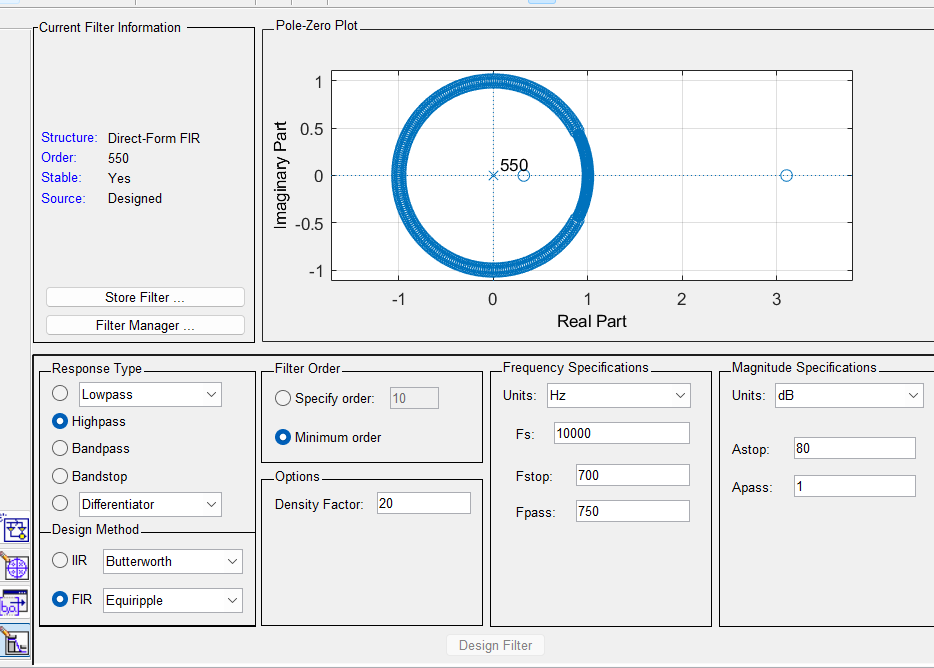

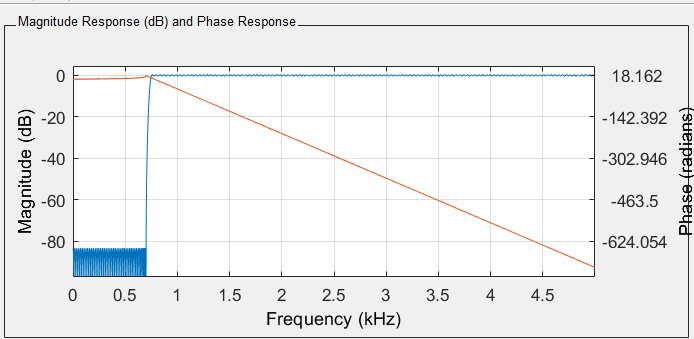

#### Analysis for the third filter; 

The third filter designed with FDAtool in MATLAB is a highpass filter with specific frequency characteristics. With a stopband frequency (fstop) of 700 Hz and a passband frequency (fpass) of 750 Hz, it's designed to attenuate frequencies below 750 Hz while allowing frequencies above 750 Hz to pass through. The stopband attenuation (Astop) of 80 dB indicates a strong suppression of frequencies below the stopband, while the passband ripple (Apass) of 1 dB ensures minimal distortion in the passband. This filter is crucial for applications where low-frequency components are unwanted or need to be removed. For instance, in audio processing, it can eliminate low-frequency noise while preserving the clarity of the desired audio signal. With a sampling frequency of 10,000 Hz, it effectively filters signals with a wide range of frequencies, making it versatile for various signal processing tasks.

#### Filter Testing 


% Load the filter coefficients from the .mat file
HundredHzFilter = load('HundredHzFilter.mat');

% Display the field names in the loaded structure
field_names = fieldnames(HundredHzFilter);
disp(field_names);

    {'HundredHzFilter'}



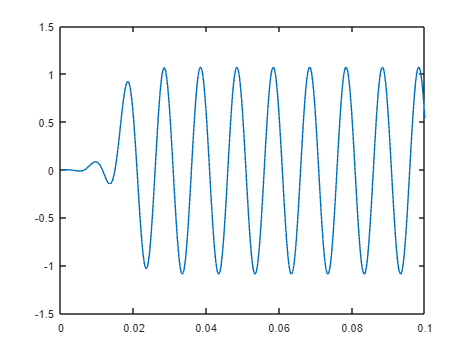

%In MATLAB, filter coefficients, such as feedforward coefficients, 
% are typically stored in a structure after designing a filter. Extracting the numerator coefficients from this structure, denoted as b, 
% is essential as they define how the input signal is processed by the filter when applying functions like filter.
Hundred_Coefficients = HundredHzFilter.HundredHzFilter;
filtered100 = filter(Hundred_Coefficients,1,composite_signal);
plot(t,filtered100);xlim([0 0.1]);

#### Trying out 500Hz Bandpass filter

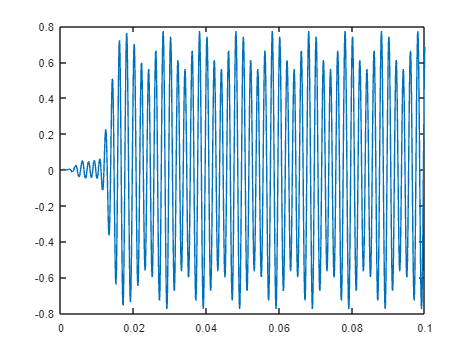

clf;
FilterFiveHundred = load('FilterFiveHundred.mat');
FiveHundred_Filter_Coefficients = FilterFiveHundred.FilterFiveHundred;
filtered500 = filter(FiveHundred_Filter_Coefficients,1,composite_signal);
plot(t,filtered500);xlim([0 , 0.1]);

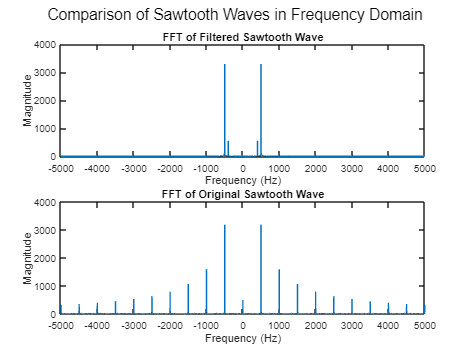

 clf;
 fil_sawtooth_wave_fft = fftshift(fft(filtered500));
 N4 = length(filtered500);
 f_axis_4 = linspace(-fs/2, fs/2, N4);
 sawtooth_wave_fft = fftshift(fft(sawtooth_signal));
 N5 = length(sawtooth_signal);
 f_axis_5 = linspace(-fs/2, fs/2, N5);
 subplot(2,1,1)
 plot(f_axis_4, abs(fil_sawtooth_wave_fft));
 title("FFT of Filtered Sawtooth Wave")
 xlabel('Frequency (Hz)');
 ylabel('Magnitude');
 subplot(2,1,2)
 plot(f_axis_5, abs(sawtooth_wave_fft));
 title("FFT of Original Sawtooth Wave")
 xlabel('Frequency (Hz)');
ylabel('Magnitude');
ylim([0 4000]);
 sgtitle("Comparison of Sawtooth Waves in Frequency Domain")

#### Analysis for the 500 Hz bandpass filter I made:

Filter didn't effectively happen due to the harmonic interference between sawtooth and square wave. This leads to the distortion/changes in the amplitude. 

Not to mention, band-pass filter itself atttenuated frequency components which were specific to the original sawtooth waveform leading to a more sine wave looking output rather than a sawtooth looking one. 

#### Trying out 800 Hz highpass filter:

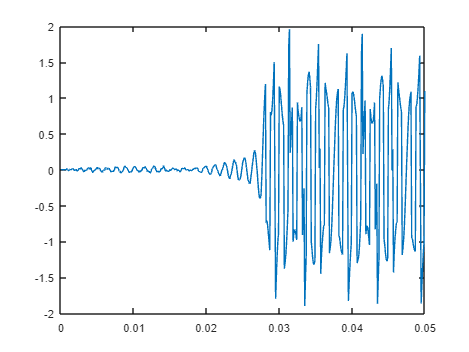

clf;
 Filter800 = load('Filter800.mat');
Filter800_Coefficient = Filter800.Filter800;
filtered800 = filter(Filter800_Coefficient,1,composite_signal);
plot(t,filtered800);xlim([0 , 0.05]);

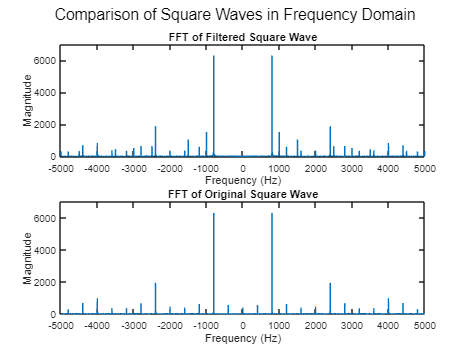

 clf;
 fil_square_wave_fft = fftshift(fft(filtered800));
 N4 = length(filtered800);
 f_axis_4 = linspace(-fs/2, fs/2, N4);
 square_wave_fft = fftshift(fft(pulse_signal));
 N5 = length(pulse_signal);
 f_axis_5 = linspace(-fs/2, fs/2, N5);
 subplot(2,1,1)
 plot(f_axis_4, abs(fil_square_wave_fft));
 title("FFT of Filtered Square Wave")
 xlabel('Frequency (Hz)');
 ylabel('Magnitude');
 ylim([0 7000]);
 subplot(2,1,2)
 plot(f_axis_5, abs(square_wave_fft));
 title("FFT of Original Square Wave")
 xlabel('Frequency (Hz)');
ylabel('Magnitude');
ylim([0 7000]);
 sgtitle("Comparison of Square Waves in Frequency Domain")

 clf;

#### Analysis:

The anticipated outcome wasn't achieved, it is an unsuccessful filtering process. 

Seeing it in frequency domain, following issues are highlighted. 

- There was interference from harmonics of the sawtooth signal

- loss of certain original signal frequencies

- the introduction of additional frequencies due to the band-stop filter application

#### Task 2

I first added the audio files into the folder, then trimmed them using the following commands

% % Load the original .wav file
% [y, Fs] = audioread('tractor-sound-ambient-farm-sounds-143615.mp3');
% 
% % Extract the first 4 seconds of audio
% duration = 4; % Duration in seconds
% num_samples = duration * Fs;
% y_shortened = y(1:min(num_samples, length(y)));
% 
% % Save the shortened audio as a new .wav file
% audiowrite('shortened_audio2.wav', y_shortened, Fs);
% 
% disp('Shortened audio saved successfully.');

Here I am loading all the three audios and combining them into one

% Load the shortened audio files
[car, car_Fs] = audioread('shortened_audio.wav');
[motor, motor_Fs] = audioread('shortened_audio2.wav');
[speech, speech_Fs] = audioread('speech.wav');

% Ensure all audio files have the same length
min_length = min([length(car), length(motor), length(speech)]);
car = car(1:min_length);
motor = motor(1:min_length);
speech = speech(1:min_length);

% Concatenate the three audio signals to create the composite signal
speech = 1.5*speech;
motor = 0.5*motor;
composite_signal = [car;motor;speech];

% Play back the composite signal
%sound(composite_signal, car_Fs);

% Add a pause between playback sessions
%pause(length(composite_signal)/car_Fs);

% Add the audio files together
y_combined = car + motor + speech;

% Save the combined audio as a new .wav file
audiowrite('combined_audio.wav', y_combined, car_Fs); % Assuming all files have the same sampling frequency

disp('Combined audio saved successfully.');

Combined audio saved successfully.


### **Combining signals to make 2 composite signals!**

 clf;
 % Combine the first two signals with the third signal
 comp_car_speech = car + speech;
 comp_car_motor = car + motor;
 % Save the composite signals as audio files
 audiowrite('comp_sig_1.wav', comp_car_speech, car_Fs);
 audiowrite('comp_sig_2.wav', comp_car_motor, car_Fs);


### Computing as well as Plotting FFTs of Composite Signals

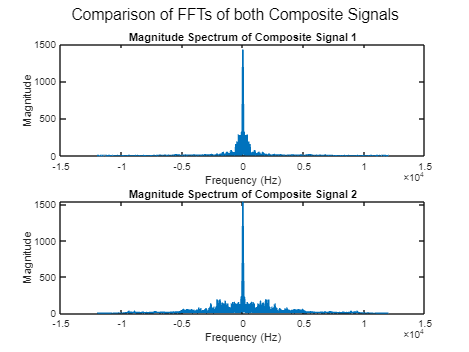

 % Load the composite signals
 [comp_car_speech, fs_comp] = audioread('comp_sig_1.wav');
 [comp_car_motor, ~] = audioread('comp_sig_2.wav');
 % Compute the FFTs of the composite signals
 fft_comp_sig_1 = fftshift(fft(comp_car_speech));
 fft_comp_sig_2 = fftshift(fft(comp_car_motor));
 % Compute the frequency axis for plotting
 N8 = length(comp_car_speech); % Assuming all composite signals have the same length
 f_axis_8 = linspace(-fs_comp/2, fs_comp/2, N8);
 % Plot the magnitude spectra
 figure;
 subplot(2, 1, 1);
 plot(f_axis_8, abs(fft_comp_sig_1));
 title('Magnitude Spectrum of Composite Signal 1');
 xlabel('Frequency (Hz)');
 ylabel('Magnitude');
 subplot(2, 1, 2);
 plot(f_axis_8, abs(fft_comp_sig_2));
 title('Magnitude Spectrum of Composite Signal 2');
 xlabel('Frequency (Hz)');
 ylabel('Magnitude');
 sgtitle("Comparison of FFTs of both Composite Signals")

**Analysis: **

As can be observed, the composite signal that combines motor and car has more higher frequency components comparitively to the one where we add car onto speech!

**Computing FFT of Disk Audio: **

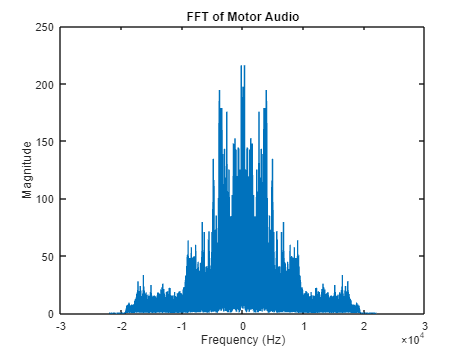

 clf;
 disk_fft = fftshift(fft(motor));
 D = length(motor); % Assuming all composite signals have the same length
 F = linspace(-motor_Fs/2, motor_Fs/2, D);
 plot(F, abs(disk_fft));
 title('FFT of Motor Audio');
 xlabel('Frequency (Hz)');
 ylabel('Magnitude');

#### Now we will be playing both composite signals that we have made

 % Playback composite signal 1
 sound(comp_car_speech, car_Fs);
 pause(length(comp_car_motor) / car_Fs + 1); % Pause for the duration of the signal plus 1 second

 % Playback composite signal 2
 sound(comp_car_motor, car_Fs);
 pause(length(comp_car_motor) / car_Fs + 1); % Pause for the duration of the signal plus 1 second


 The human voice is abit overshadowed by the car audio in the first signal. The motor audio is comparatively more audible in the second composite signal. 

This is due to the difference accounts for the higher frequencies observed in the FFT of the second composite signal.

#### Extracting speech

 clf;
 human_fft = fftshift(fft(speech));
 N9 = length(speech);
 f_axis_9 = linspace(-speech_Fs/2, speech_Fs/2, N9);
 cutoff_frequency = 600;
 % Design a high-pass filter
 filter_order = 6; % Filter order
 [b, a] = butter(filter_order, cutoff_frequency/(speech_Fs/2), 'low');
 % Apply the filter to the first composite signal
 fil_comp_1 = filter(b, a, comp_car_speech);

 %Playback the filtered composite signal
soundsc(fil_comp_1, speech_Fs);
pause(length(fil_comp_1)/speech_Fs + 1);


#### **Plotting filtered and unfiltered FFTs of human speech**

% Suppress warnings to avoid cluttering the output
warning('off');

% Compute the FFT of the filtered composite signal for human voice and shift it to center frequencies
fil_human_fft = fftshift(fft(fil_comp_1));

% Obtain the length of the filtered composite signal for human voice
N10 = length(fil_comp_1);

% Create the frequency axis for the filtered human voice signal
f_axis_10 = linspace(-speech_Fs/2, speech_Fs/2, N10);

% Plot the FFT of the filtered human voice signal
subplot(2,1,1);
plot(f_axis_10, fil_human_fft);
ylim([0 200]); % Limit the y-axis for better visualization
title('FFT of Filtered Human Voice Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Plot the FFT of the original human voice signal
subplot(2,1,2);
plot(f_axis_9, abs(human_fft)); % Assuming f_axis_9 is defined elsewhere
xlim([-2500 2500]); % Limit the x-axis for better visualization
title('FFT of Original Human Voice Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Set a common title for the comparison of original and filtered human voice signals
sgtitle("Comparison of Original & Filtered Human Voice Signal");


Although there is an overlap with the motor audio, extracting human audio as it is is very challenging. However, we can distinguish the human voice easily in the filtered output.

#### Extracting motor from motor + car

  clf;
 motor_fft = fftshift(fft(motor));
 N11 = length(motor);
 f_axis_11 = linspace(-motor_Fs/2, motor_Fs/2, N9);
 cutoff_frequency = 1300;
 % Design a high-pass filter
 filter_order = 6; % Filter order
 [b, a] = butter(filter_order, cutoff_frequency/(motor_Fs/2), 'low');
 % Apply the filter to the first composite signal
 fil_comp_2 = filter(b, a, comp_car_motor);

 %Playback the filtered composite signal
 soundsc(fil_comp_2, motor_Fs);
pause(length(fil_comp_2)/motor_Fs + 1);


#### Plotting FFT

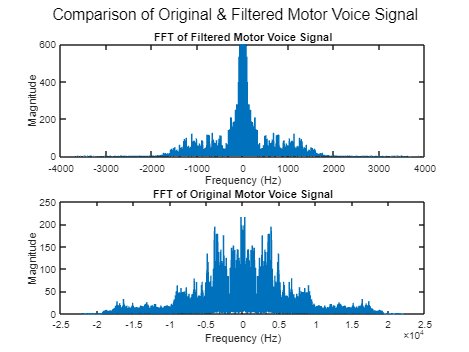

% Compute the FFT of the filtered composite signal and shift it to center frequencies
fil_motor_fft = fftshift(fft(fil_comp_2));

% Obtain the length of the filtered composite signal
N12 = length(fil_comp_2);

% Create the frequency axis for the filtered signal
f_axis_12 = linspace(-motor_Fs/2, motor_Fs/2, N12);

% Plot the FFT of the filtered motor voice signal
subplot(2,1,1);
plot(f_axis_12, fil_motor_fft);
ylim([0 600]); % Limit the y-axis for better visualization
title('FFT of Filtered Motor Voice Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Plot the FFT of the original motor voice signal
subplot(2,1,2);
plot(f_axis_11, abs(motor_fft)); % Assuming f_axis_11 is defined elsewhere
title('FFT of Original Motor Voice Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Set a common title for the comparison of original and filtered motor voice signals
sgtitle("Comparison of Original & Filtered Motor Voice Signal");

Extrating motor audio accurately is very difficult, however, using high-pass filter still significantly clarifies the motor audio for us.